# Clean Timetable with Missing, Duplicate, or Nonuniform Times

This example shows how to create a *regular* timetable from one that has missing, duplicate, or nonuniform times. A timetable is a type of table that associates a time-stamp, or *row time*, with each row of data. In a regular timetable, the row times are sorted and unique, and differ by the same regular time step.

Also, some toolboxes have functions that work on regularly spaced time series data in the form of numeric arrays. So the example also shows how to export the data from a timetable for use with other functions.

There are a number of issues with row times that can make timetables irregular. The row times can be missing. They can be out of order. They can be duplicates, creating multiple rows with the same time that might have the same or different data. And even when they are present, sorted, and unique, they can differ by time steps of different sizes.

Timetables provide a number of different ways to resolve missing, duplicate, or nonuniform times, and to resample or aggregate data to create regular row times.

- To find missing row times, use [`ismissing`](docid:matlab_ref#bty8cec-1).

- To remove missing times and data, use [`rmmissing`](docid:matlab_ref#bvcl6_c).

- To sort a timetable by its row times, use [`sortrows`](docid:matlab_ref#bt8bwzx-1).

- To make a timetable with unique and sorted row times, use [`unique`](docid:matlab_ref#bs_6vpd-1) and [`retime`](docid:matlab_ref#bvdhiwr).

- To remove duplicate times, specify a vector of unique times and use `retime`.

- To make a regular timetable, specify a regular time vector and use `retime`.

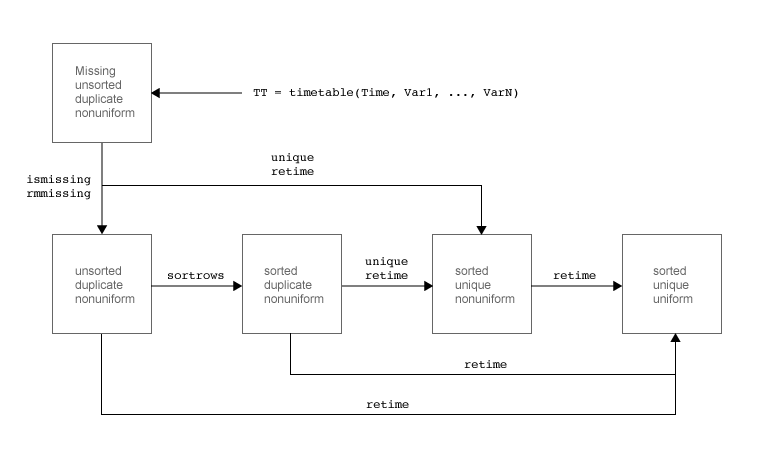

## Load Timetable

Load a sample timetable from the MAT-file `badTimes` that contains weather measurements taken over several hours on June 9, 2016. The timetable `TT` includes temperature, rainfall, and wind speed measurements taken at irregular times during that day.

load badTimes
TT

## Find and Remove Rows with Missing Row Times

One way to begin is by finding and removing rows that have a `NaT`, or missing value, as the row time. To find missing values in the vector of row times, use `ismissing`. The `ismissing` function returns a logical vector that contains `1` wherever `TT.Time` has a missing value.

natRowTimes = ismissing(TT.Time)

To keep only those rows that do not have missing values as row times, index into `TT` using `~natRowTimes` as row indices. Assign those rows to a new timetable, `goodRowTimesTT`.

goodRowTimesTT = TT(~natRowTimes,:)

This method removes only the rows that have missing row times. The timetable variables still might have missing data values. For example, the last row of `goodRowTimesTT` has `NaN` values for the `Rain` and `Windspeed` variables.

## Remove Rows with Missing Times and Missing Data

As an alternative, you can remove both missing row times and missing data values at the same time by using the `rmmissing` function. `rmmissing` removes any timetable rows that have missing row times, missing data values, or both.

Display the missing row time and missing data values of `TT`.

TT

Remove all rows that have missing row times or data values. Assign the remaining rows to the timetable `goodValuesTT`.

goodValuesTT = rmmissing(TT)

## Sort Timetable and Determine If It Is Regular

After dealing with missing values, you can go on to sort your timetable and then determine if the sorted timetable is regular.

To determine if `goodValuesTT` is already sorted, use the `issorted` function.

tf = issorted(goodValuesTT)

Since it is not, sort the timetable on its row times by using the `sortrows` function.

sortedTT = sortrows(goodValuesTT)

Determine whether `sortedTT` is regular. A regular timetable has the same time interval between consecutive row times. Even a sorted timetable can have time steps that are not uniform.

tf = isregular(sortedTT)

Since it is not, display the differences between row times.

diff(sortedTT.Time)

Since the row times are sorted, this result shows that some row times are unique and some are duplicates.

## Remove Duplicate Rows

Timetables can have duplicate rows. Timetable rows are duplicates if they have the same row times and the same data values. In this example, the last two rows of `sortedTT` are duplicate rows. (There are other rows in `sortedTT` that have duplicate row times but differing data values.)

To remove the duplicate rows from `sortedTT`, use `unique`. The `unique` function returns the unique rows and sorts them by their row times.

uniqueRowsTT = unique(sortedTT)

## Find Rows with Duplicate Times and Different Data

Timetables can have rows with duplicate row times but different data values. In this example, `uniqueRowsTT` has several rows with the same row times but different values.

Find the rows that have duplicate row times. First, sort the row times and find consecutive times that have no difference between them. Times with no difference between them are the duplicates. Index back into the vector of row times and return a unique set of times that identify the duplicate row times in `uniqueRowsTT`.

dupTimes = sort(uniqueRowsTT.Time);
tf = (diff(dupTimes) == 0);
dupTimes = dupTimes(tf);
dupTimes = unique(dupTimes)

To display the rows with duplicate row times, index into `uniqueRowsTT` using `dupTimes`. When you index on times, the output timetable contains all rows with matching row times.

uniqueRowsTT(dupTimes,:)

## Select First and Last Rows with Duplicate Times

When a timetable has rows with duplicate times, you might want to select particular rows and discard the other rows having duplicate times. For example, you can select either the first or the last of the rows with duplicate row times by using the `unique` and `retime` functions.

First, create a vector of unique row times from `TT` by using `unique`.

uniqueTimes = unique(uniqueRowsTT.Time)

Select the first row from each set of rows that have duplicate times. To copy data from the first rows, specify the `'firstvalue'` method.

firstUniqueRowsTT = retime(uniqueRowsTT,uniqueTimes,'firstvalue')

Select the last rows from each set of rows that have duplicate times. To copy data from the last rows, specify the `'lastvalue'` method.

lastUniqueRowsTT = retime(uniqueRowsTT,uniqueTimes,'lastvalue')

As a result, the last two rows of `firstUniqueRowsTT` and `lastUniqueRowsTT` have different values in the `Temp` variable.

## Aggregate Data from All Rows with Duplicate Times

Another way to deal with data in the rows having duplicate times is to aggregate or combine the data values in some way. For example, you can calculate the means of several measurements of the same quantity taken at the same time.

Calculate the mean temperature, rainfall, and wind speed for rows with duplicate row times using the `retime` function.

meanTT = retime(uniqueRowsTT,uniqueTimes,'mean')

As a result, the last two rows of `meanTT` have mean temperatures in the `Temp` variable for the rows with duplicate row times.

## Make Timetable Regular

Finally, you can resample data from an irregular timetable to make it regular by using the `retime` function. For example, you can interpolate the data from `meanTT` onto a regular hourly time vector. To use linear interpolation, specify `'linear'`. Each row time in `hourlyTT` begins on the hour, and there is a one-hour interval between consecutive row times.

hourlyTT = retime(meanTT,'hourly','linear')

Instead of using a predefined time step such as `'hourly'`, you can specify a time step of your own. To specify a time step of 30 minutes, use the `'regular'` input argument and the `'TimeStep'` name-value argument. You can specify a time step of any size as a `duration` or `calendarDuration` value.

regularTT = retime(meanTT,'regular','linear','TimeStep',minutes(30))

## Extract Regular Timetable Data into Array

You can export the timetable data for use with functions to analyze data that is regularly spaced in time. For example, the Econometrics Toolbox™ and the Signal Processing Toolbox™ have functions you can use for further analysis on regularly spaced data.

Extract the timetable data as an array. You can use the `Variables` property to return the data as an array, as long as the table variables have data types that allow them to be concatenated.

A = regularTT.Variables

`regularTT.Variables` is equivalent to using curly brace syntax, `regularTT{:,:}`, to access the data in the timetable variables.

A2 = regularTT{:,:}

*Copyright 2016-2021 The MathWorks, Inc.*